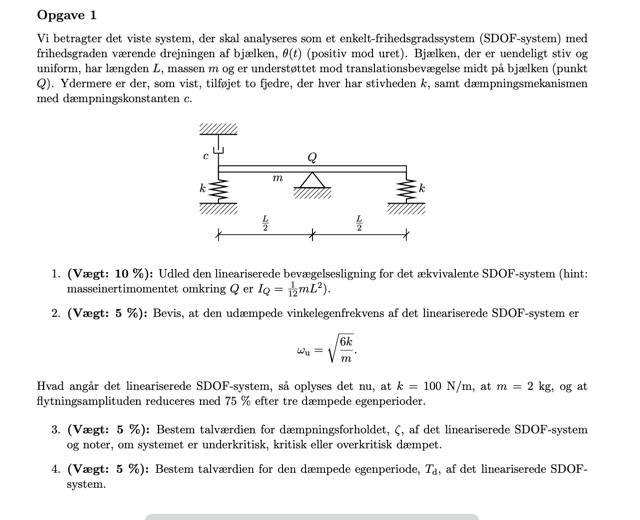

1.1 Vi udtrykker det resulterende moment omkring $Q$ som:


$$I_Q \ddot{\theta} =-2k\;\frac{L}{2}\cdot \sin \left(\theta \;\right)\frac{L}{2}\cos \left(\theta \right)-c\;\frac{L}{2}\dot{\theta} \;\cos \;\theta \;\frac{L}{2}\cos \theta$$


Med LTI-antagelser har vi at $\sin(\theta) \approx \theta$ og $\cos(\theta) \approx 1$ således at det ovenstående reduceres til

$I_Q \ddot{\theta} =-2k\;\frac{L^2 }{4}\cdot \theta -c\;\frac{L^2 }{4}\dot{\theta}$ => $I_Q \ddot{\theta} +c\frac{L^2 \;}{4}\dot{\theta} +2k\;\frac{L^2 }{4}\theta =0$

Med $I_Q =\frac{1}{12}m\;L^2$ bliver dette


$$\frac{1}{12}m\;L^2 \;\ddot{\theta} +c\frac{L^2 \;}{4}\dot{\theta} +2k\;\frac{L^2 }{4}\theta =0$$


1.2 Vi kan omskrive det ovenstående til en form hvor koefficienten til $\ddot{\theta}$ bliver $1$, altså


$$\ddot{\theta} +\frac{12c}{4m}\;\dot{\theta} +\frac{24k}{4m}\theta =\ddot{\theta} +3\frac{c}{m}\dot{\theta} +6\;\frac{k}{m}\theta =0$$


På denne form er vores udtryk den rotationelle analogi til


$$\ddot{d} \left(t\right)+2\zeta \omega_u \dot{d} \left(t\right)+\omega_u^2 d\left(t\right)$$


Altså kan vi ved inspektion finde

$\omega_u^2 =6\;\frac{k}{m}$ => $\omega_u =\sqrt{\;\frac{6k}{m}}$

1.3

k = 100; % N/m
m = 2; % kg

omega_u = sqrt(6 * k / m);

Vi ved at den logaritmiske nedsættelse (eng: Logarithmic decrement) er givet ved:


$$\delta =\frac{1}{j}\log \left(\frac{d\left(t\right)}{d\left(t+{j\;T}_d \right)}\right)$$


I dette tilfælde får vi:

j = 3;
dt_dec = 0.75;

delta = 1/j * log(1/dt_dec);

Og dernæst kan dæmpningsforholdet estimeres som:


$$\zeta =\frac{\delta }{\sqrt{\;\delta^2 +4\pi^2 }}$$


zeta = delta/sqrt(delta^2 + 4 * pi^2)

zeta = 0.0153

Da $\zeta =0\ldotp 0153<1$ er dæmpningen underkritisk.

1.4

Den dæmpede egenfrekvens $\omega_d$ er givet ved


$$\omega_d =\omega_u \sqrt{1-\zeta^2 }$$


Så:

omega_d = omega_u * sqrt(1 - zeta^2);
T_d = 2 * pi/omega_d

T_d = 0.3628

Altså er den dæmpede egenperiode $T_d \approx 0\ldotp 3628\;s$.

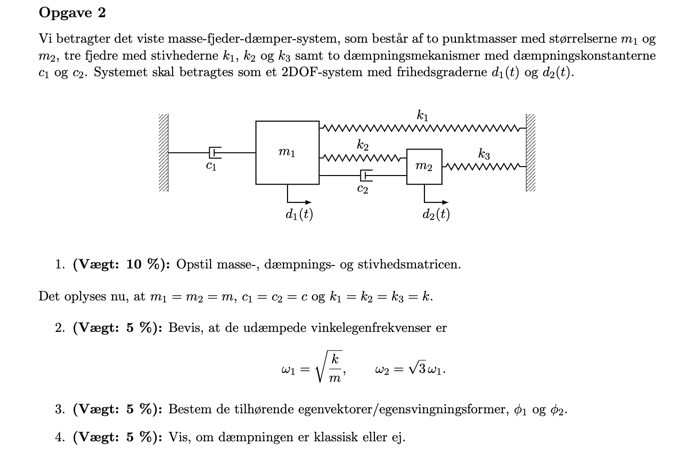

2.1 Vha. en kraftbalance kan vi opstille de to følgende udtryk


$$m_1 \ddot{\;d_1 } =-c_1 \dot{d_1 } -k_1 d_1 +k_2 \left(d_2 -d_1 \right)+c_2 \left(\dot{d_2 } -\dot{d_1 } \right)$$



$$m_1 \ddot{\;d_1 } +c_1 \dot{d_1 } +k_1 d_1 -k_2 \left(d_2 -d_1 \right)-c_2 \left(\dot{d_2 } -\dot{d_1 } \right)=0$$


og


$$m_2 \ddot{d_2 } =-k_2 \left(d_2 -d_1 \right)-c_2 \left(\dot{d_2 } -\dot{d_1 } \right)-k_3 d_2$$



$$m_2 \ddot{d_2 } +k_2 \left(d_2 -d_1 \right)+c_2 \left(\dot{d_2 } -\dot{d_1 } \right)+k_3 d_2 =0$$


Vi kan samle disse to udtryk til:


$$\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
c_1 +c_2  & -c_2 \\
-c_2  & c_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
k_1 +k_2  & -k_2 \\
-k_2  & k_2 +k_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


2.2 Med de givne størrelser fås følgende system


$$\left\lbrack \begin{array}{cc}
m & 0\\
0 & m
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2c & -c\\
-c & c
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2k & -k\\
-k & 2k
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Vi har desuden, at vores karakteristiske ligning er


$$\det \left(K-\omega^2 M\right)=0$$


$\det \left(\left\lbrack \begin{array}{cc}
2k-\omega^2 m & -k\\
-k & 2k-\omega^2 m
\end{array}\right\rbrack \right)=0$ => ${\left(2k-\omega^2 m\right)}^2 -{\left(-k\right)}^2 =0$

Hvilket vi løser i MatLab som:

syms k omega m c positive
M = [m 0; 0 m];
C = [2*c  -c; -c   c  ];
K = [2*k  -k; -k   2*k];

% Karakteritisk ligning: det(K - omega^2 M) = 0
char_eq = det(K - omega^2*M);

disp("Karakteristisk ligning")

Karakteristisk ligning


pretty(char_eq)

   2          2    2  4
3 k  - 4 k m ω  + m  ω




% Solve for omega
omega_sol = solve(char_eq == 0, omega)

$$omega\_sol = \left(\begin{array}{c} \frac{\sqrt{k}}{\sqrt{m}}\\ \frac{\sqrt{3}\,\sqrt{k}}{\sqrt{m}} \end{array}\right)$$

Altså er det vist.

2.3

Her løser vi egenvektor-problemet:


$$\det \left(\left\lbrack \begin{array}{cc}
2k-\omega^2 m & -k\\
-k & 2k-\omega^2 m
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
\phi_1 \\
\phi_2 
\end{array}\right\rbrack =0$$


for begge vores egenværdier.

omega_1sq = k/m;
omega_2sq = 3 * k/m;

A1 = simplify(K - omega_1sq*M);

null(A1)

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$


A2 = simplify(K - omega_2sq * M);

null(A2)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

Altså får vi:


$$\phi_1 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$$



$$\phi_2 =\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$$


2.4 Fra 2.3 har vi vores modalmatrice:


$$\Phi =\left\lbrack \begin{array}{c}
\phi_{1,1} \;\;\;\;|\;\;\;\;\phi_{2,1} \\
\phi_{1,2} \;\;\;\;|\;\;\;\;\phi_{2,2} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & -1\\
1 & 1
\end{array}\right\rbrack$$


For at finde ud af om vores dæmpning er klassisk skal vi bestemme om den modale dæmpningsmatrice $\tilde{C}$ er diagonal. Denne er givet som:

$\tilde{C} =\Phi^T C\Phi \;$:

Phi = [1  -1; 1  1];

C_tilde = Phi' * C * Phi

$$C\_tilde = \left(\begin{array}{cc} c & -c\\ -c & 5\,c \end{array}\right)$$

Da $\tilde{C} =\left\lbrack \begin{array}{cc}
c & -c\\
-c & 5c
\end{array}\right\rbrack$ ikke er diagonal er vores dæmpning ikke klassisk.

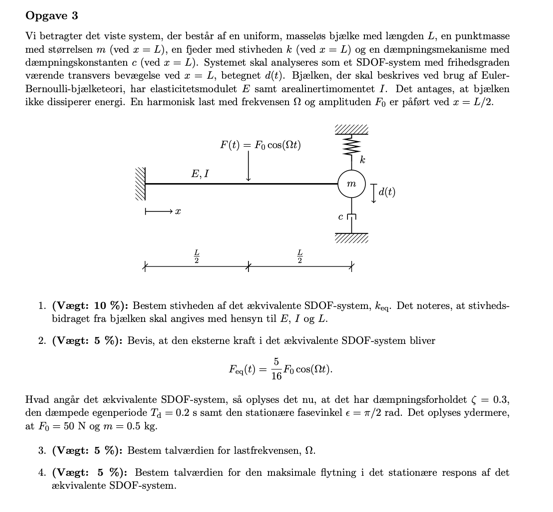

3.1 Fra D'Alemberts princip har vi at 


$$d\left(t\right)=\delta_{21} F\left(t\right)-\delta_{22} m\ddot{d} \left(t\right)-\delta_{22} c\dot{d} \left(t\right)+k\;d\left(t\right)\Rightarrow \;\;\;m\;\ddot{d} \left(t\right)+c\dot{d} \left(t\right)+\left(\frac{1}{\delta_{22} }+k\right)d\left(t\right)=\frac{\delta_{21} }{\delta_{22} }F\left(t\right)$$


Herfra ser vi at $m_{eq} = m, c_{eq} = c, k_{eq} = (\delta_{22} + k)^{-1}, F_{eq} = \frac{\delta_{21}}{\delta_{22}} F(t)$.

Fra statik ved vi at forskydningen $\delta_{22}$ i en knægtbjælke med last $P$ påført på enden er


$$\Delta_{\max } =\frac{P\cdot L^3 }{3E\;I}$$


I dette tilfælde påfører vi en enhedslast $P = 1$ således at


$$\delta_{22} = \frac{L^3}{3EI}$$


Hvorfor vi får at


$$k_{\mathrm{eq}} =\delta_{22}^{-1} +k=3\frac{\mathrm{EI}\;}{L^3 }+k$$


3.2

Vi har udledt at 


$$F_{\mathrm{eq}} \left(t\right)=\frac{\delta_{21} }{\delta_{22} }F\left(t\right)$$


og vi mangler altså blot at finde forskydningen i punkt 2 (ved massen) forårsaget af en punktlast ved kraften, dette er $\delta_{21}$.

Fra Statik ved vi at endeforskydningen af en midterbelastet knægtbjælke er


$$v_{\max } =\frac{5P\;L^3 }{48E\;I}$$


Altså


$$\delta_{21} =\frac{5L^3 }{48E\;I}$$


Altså:

syms E I L
delta_21 = 5 * L^3 / (48 * E * I);
delta_22 = L^3/(3 * E * I);

F_eq = simplify(delta_21/delta_22)

$$F\_eq = \frac{5}{16}$$

Altså er det vist at koefficienten til kraften skal være 5/16. 

3.3

Det oplyses at $\epsilon = \frac{\pi}{2}$ hvorfor vi har resonans, dermed har vi at


$$\Omega =\omega_u$$


Vi ved desuden at den udæmpede vinkelegenfrekvens kan findes fra den dæmpede samt dæmpningsforholdet som:


$$\omega_u =\frac{\omega_d }{\sqrt{1-\zeta^2 }}$$


Desforuden er den dæmpede vinkelegenfrekvens $\omega_d$ relateret til den dæmpede egenperiode $T_d = 0.2 s$ som:


$$\omega_d =\frac{2\pi }{T_d }\;\;\;\Rightarrow \Omega =\omega_u =\frac{2\pi }{T_d \sqrt{1-\zeta^2 }}$$


Altså

T_d = 0.2; %s
zeta = 0.3;

omega_u = 2 * pi / (T_d * sqrt(1- zeta^2));
Omega = omega_u

Omega = 32.9328

Altså er lastfrekvensen $\Omega =32\ldotp 933\;\frac{\mathrm{rad}}{s}$.

3.4

Den stationære flytningsrespons er:


$$d_{\mathrm{ss}} \left(t\right)=B\;\cos \left(\Omega \;t-\epsilon \right)$$


Den maksimale flytning må så være for $cos(\Omega t -\epsilon) = 1$ => $d_p(t) = B$. Altså er vores maksimale stationære flytning blot amplituden af den stationære flytningsrespons.

Vi har, for $p = 1$ at


$$D=\frac{B\;k_{\mathrm{eq}} }{F_{\mathrm{eq}} }=\frac{1}{2\zeta }\Rightarrow B=\frac{F_{\mathrm{eq}} }{2\;k_{\mathrm{eq}} \zeta }=\frac{F_{\mathrm{eq}} }{2\omega_u^2 \cdot m\cdot \zeta }$$


Altså

F_0 = 50; %N
m = 0.5; %kg

F_eq = 5/16 * F_0;

B = F_eq/(2 * omega_u^2 * m * zeta)

B = 0.0480

Altså er den maksimale flytning i den stationære respons $B=0\ldotp 048\;m=4\ldotp 8\;\mathrm{cm}$.

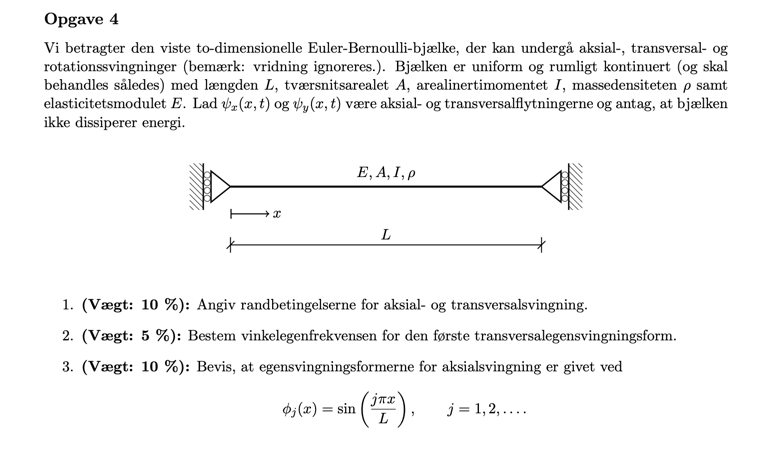

4.1

Begge støtter hindrer aksial forskydning således at


$$\psi_x \left(0,t\right)=0\;\;\;\Rightarrow \;\phi_j \left(0\right)=0$$



$$\psi_x \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j \left(L\right)=0$$


Støtterne hindrer ikke transversalforskydning så her er vi i stedet nødt til at bruge en anden randbetingelse.

Idet støtterne ikke yder modstand mod transversalforskydning må det gælde at den transverse reaktionskraft ydet af disse er 0. Således får vi at


$$V\left(0,t\right)=V\left(L,t\right)=0$$


For en Euler-Bernoulli bjælke (generelt for alle bjælker med konstant "flexural rigidity") gælder


$$V\left(x\right)=E\;I\frac{d^3 v\;}{{d\;x}^3 }$$


Vores randbetingelse her er $V\left(0,t\right)=V\left(L,t\right)=0\Rightarrow \;\mathrm{EI}\frac{\;d^3 v}{{\mathrm{dx}}^3 }=0\Rightarrow \frac{d^3 v}{{\mathrm{dx}}^3 }\left(0,t\right)=\frac{d^3 v}{{\mathrm{dx}}^3 }\left(L,t\right)=0$

Det samme gør sig gældende for momenter, idet støtterne ikke kan understøtte et moment. Her gælder


$$M\left(x\right)=\mathrm{EI}\frac{d^2 v\;}{{\mathrm{dx}}^2 }=0\;\;\;\Rightarrow \;\;\;\;\frac{d^2 v\;}{{\mathrm{dx}}^2 }\left(0,t\right)=\frac{d^2 v\;}{{\mathrm{dx}}^2 }\left(L,t\right)=0$$


Altså er vores randbetingelser


$$\psi_x \left(0,t\right)=0\;\;\;\Rightarrow \;\;\;\;\phi_j^x \left(0\right)=0$$



$$\psi_x \left(L,t\right)=0\;\;\;\Rightarrow \;\;\;\;\phi_j^x \left(L\right)=0$$



$${{\psi_y }^{\prime } }^{\prime } \left(0,t\right)=0\;\;\;\Rightarrow \;\;\;{{\phi_j^y }^{\prime } }^{\prime } \left(0\right)=0$$



$${{\psi_y }^{\prime } }^{\prime } \left(L,t\right)=0\;\;\;\Rightarrow \;\;\;{{\phi_j^y }^{\prime } }^{\prime } \left(L\right)=0$$



$${{{\psi_y }^{\prime } }^{\prime } }^{\prime } \left(0,t\right)=0\;\;\;\Rightarrow \;\;\;\;{{{\phi_j^y }^{\prime } }^{\prime } }^{\prime } \left(0\right)=0$$



$${{{\psi_y }^{\prime } }^{\prime } }^{\prime } \left(L,t\right)=0\;\;\;\Rightarrow \;\;\;\;{{{\phi_j^y }^{\prime } }^{\prime } }^{\prime } \left(L\right)=0$$


4.2 Idet der ikke er nogen hindring mod stivlegemebevægelse i den transverse retning må den første egensvinginskonfiguration være selvsamme stivlegemebevægelse således at $\omega_1 = 0$.

4.3 Vi verficerer at det givne udtryk overholder randbetingelserne:

syms L
syms j integer
phi_j = @(x) sin (j * pi * x / L);

phi_j(0)

$$ans = 0$$

simplify(phi_j(L))

$$ans = 0$$

Altså er det vist at den givne formel for egensvingen overholder randbetingelserne.